## **1. 生成正交表**

% 定义每个因素的水平
factor_levels = {
    [1, 2];      % A：2 水平
    [1, 2, 3];   % B：3 水平
    [1, 2];      % C：2 水平
    [1, 2];      % D：2 水平
    [1, 2, 3];   % E：3 水平
    [1, 2, 3]    % F：3 水平
};

% 生成全因子设计
[comb_A, comb_B, comb_C, comb_D, comb_E, comb_F] = ndgrid(factor_levels{:});
full_factorial = [comb_A(:), comb_B(:), comb_C(:), comb_D(:), comb_E(:), comb_F(:)];

% 显示实验设计
factor_names = {'A', 'B', 'C', 'D', 'E', 'F'};
disp('全因子实验设计方案:');

全因子实验设计方案:


disp(array2table(full_factorial, 'VariableNames', factor_names));

    A    B    C    D    E    F
    _    _    _    _    _    _

    1    1    1    1    1    1
    2    1    1    1    1    1
    1    2    1    1    1    1
    2    2    1    1    1    1
    1    3    1    1    1    1
    2    3    1    1    1    1
    1    1    2    1    1    1
    2    1    2    1    1    1
    1    2    2    1    1    1
    2    2    2    1    1    1
    1    3    2    1    1    1
    2    3    2    1    1    1
    1    1    1    2    1    1
    2    1    1    2    1    1
    1    2    1    2    1    1
    2    2    1    2    1    1
    1    3    1    2    1    1
    2    3    1    2    1    1
    1    1    2    2    1    1
    2    1    2    2    1    1
    1    2    2    2    1    1
    2    2    2    2    1    1
    1    3    2    2    1    1
    2    3    2    2    1    1
    1    1    1    1    2    1
    2    1    1    1    2    1
    1    2    1    1    2    1
    2    2    1    1    2    1
    1    3    1    1    2    1
    2    3    1    1    2    1
    1  

**3. 模拟数据收集**

您可以在实际实验中替换此模拟数据收集部分。

% 假设响应变量是一个函数，您可以替换为真实实验数据
num_experiments = size(full_factorial, 1);

% 定义一个模拟的响应变量函数（您可以根据需要调整公式）
response = 10 * full_factorial(:, 1) + ...
           5  * full_factorial(:, 2) + ...
           3  * full_factorial(:, 3) + ...
           2  * full_factorial(:, 4) + ...
           8  * full_factorial(:, 5) + ...
           6  * full_factorial(:, 6) + ...
           randn(num_experiments, 1); % 加入随机误差

% 保存实验数据
experiment_data = [full_factorial, response];
disp('实验数据（包含响应变量）：');

实验数据（包含响应变量）：


disp(array2table(experiment_data, 'VariableNames', [factor_names, {'Response'}]));

    A    B    C    D    E    F        Response    
    _    _    _    _    _    _    ________________

    1    1    1    1    1    1    33.4921824497218
    2    1    1    1    1    1    43.6794244933998
    1    2    1    1    1    1    39.0124690413616
    2    2    1    1    1    1    45.9708226585959
    1    3    1    1    1    1    43.5429853591284
    2    3    1    1    1    1    55.2424484063907
    1    1    2    1    1    1    35.9332986010153
    2    1    2    1    1    1    47.9337281626712
    1    2    2    1    1    1    42.3503210013561
    2    2    2    1    1    1    51.9709942362913
    1    3    2    1    1    1     47.182452167506
    2    3    2    1    1    1    55.4349439858493
    1    1    1    2    1    1    35.9154605201823
    2    1    1    2    1    1    47.6039463506029
    1    2    1    2    1    1    41.0983477746401
    2    2    1    2    1    1    51.0413736134896
    1    3    1    2    1    1    45.2658308873033
    2    3    1    2    1    1

**4. 主效应分析**

计算每个因素的主效应：

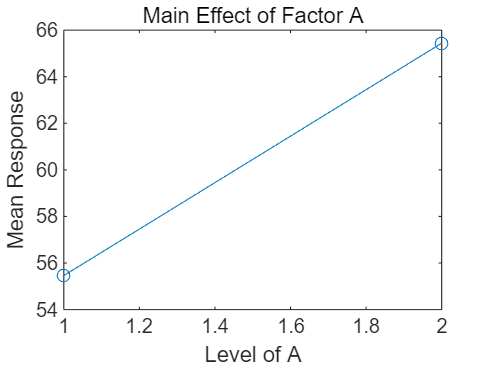

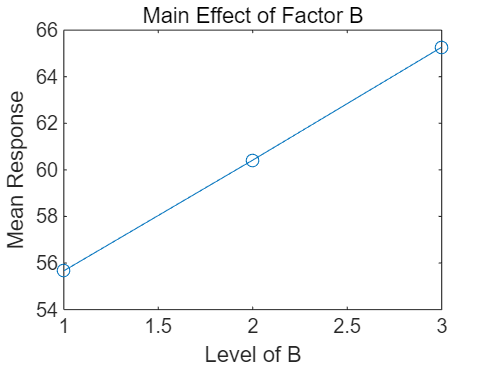

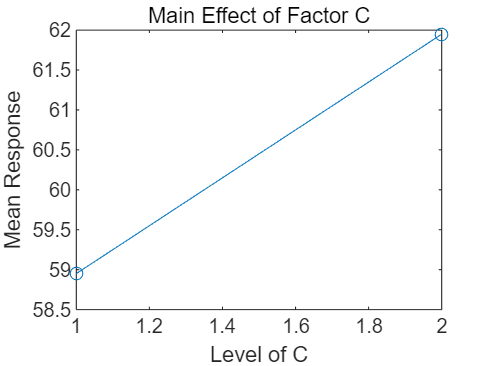

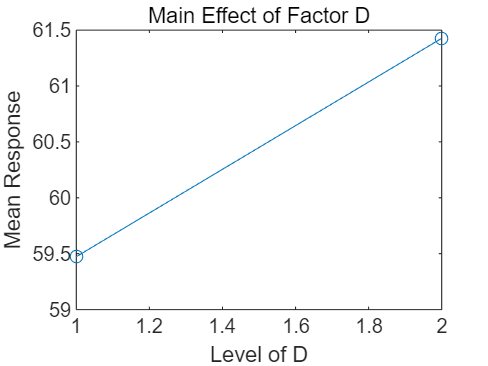

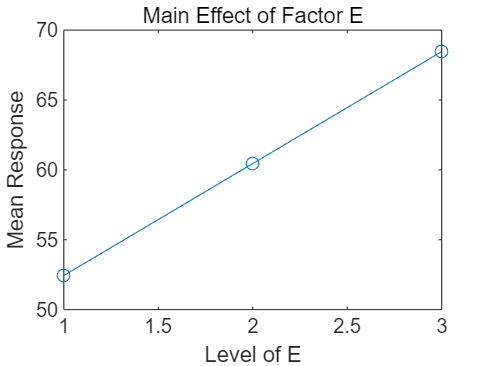

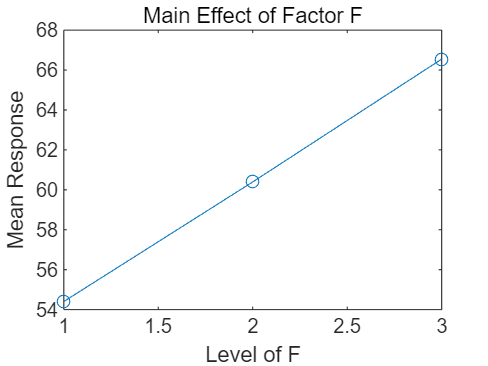

% 主效应计算
for i = 1:length(factor_names)
    levels = unique(full_factorial(:, i)); % 当前因素的所有水平
    effects = zeros(size(levels));
    for j = 1:length(levels)
        effects(j) = mean(response(full_factorial(:, i) == levels(j))); % 平均响应
    end
    
    % 绘制主效应图
    figure;
    plot(levels, effects, '-o');
    xlabel(['Level of ', factor_names{i}]);
    ylabel('Mean Response');
    title(['Main Effect of Factor ', factor_names{i}]);
end

**5. 方差分析 (ANOVA)**

使用 MATLAB 内置函数进行方差分析：

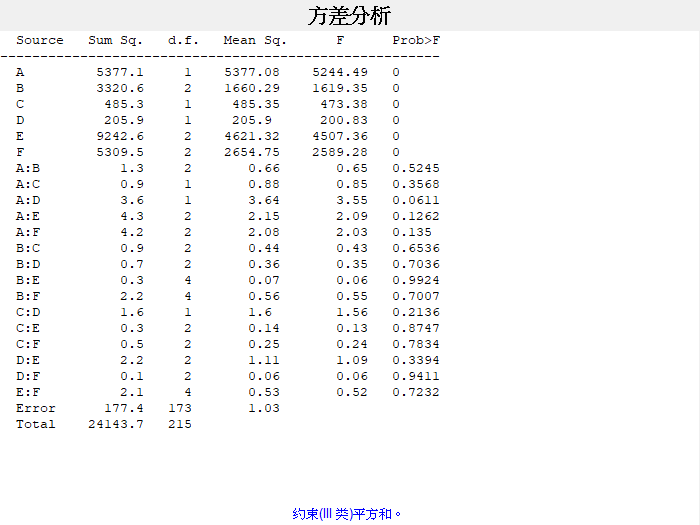

% % 创建表格数据用于 ANOVA
% factor_table = array2table(experiment_design, 'VariableNames', factor_names);
% response_table = array2table(response, 'VariableNames', {'Response'});
% 
% % 合并数据
% anova_data = [factor_table, response_table];
% 
% % 方差分析
% anova_result = anovan(response, {experiment_design(:, 1), experiment_design(:, 2), ...
%     experiment_design(:, 3), experiment_design(:, 4), experiment_design(:, 5), experiment_design(:, 6)}, ...
%     'model', 'linear', 'varnames', factor_names);

% 使用 MATLAB 的 anovan 函数分析交互作用
anova_result = anovan(response, ...
    {full_factorial(:, 1), full_factorial(:, 2), full_factorial(:, 3), ...
     full_factorial(:, 4), full_factorial(:, 5), full_factorial(:, 6)}, ...
    'model', 'interaction', 'varnames', factor_names);


% 显示 ANOVA 结果
disp('ANOVA 方差分析结果:');

ANOVA 方差分析结果:


disp(anova_result);

     2.55116492085876e-131
     9.74990253561257e-113
       2.1513539174226e-51
      9.33377367324184e-31
     5.93634733163483e-150
     1.19502160827072e-129
         0.524513012644678
         0.356801720551667
        0.0610965922491044
         0.126244680856682
         0.135008367566902
         0.653580038725086
         0.703585090960646
          0.99244314592704
         0.700741516819904
         0.213617826792738
         0.874743283280328
         0.783394579852259
         0.339355194412191
         0.941054821641143
         0.723165447038301



**6. 优化分析**

通过分析主效应和方差分析结果，选择响应变量最大的因素组合：

% 找到响应变量最大的实验组合
[optimal_response, optimal_index] = max(response);
optimal_combination = full_factorial(optimal_index, :);

disp('最优实验组合:');

最优实验组合:


disp(array2table(optimal_combination, 'VariableNames', factor_names));

    A    B    C    D    E    F
    _    _    _    _    _    _

    2    3    2    2    3    3



disp(['最大响应值: ', num2str(optimal_response)]);

最大响应值: 87.5894
